IAE = 108958.2511			P = 23.0476		I = 2.9469		D = 0.79466
IAE = 90162.0252			P = 24.8127		I = 3.071		D = 0.3588
IAE = 850437.8642			P = 28.8623		I = 5.6916		D = 2.1721
IAE = 109574.1024			P = 22.3334		I = 7.6981		D = 0.64956
IAE = 82954.3127			P = 18.0356		I = 9.0736		D = 0.019096
IAE = 357930.5135			P = 13.8865		I = 3.7241		D = 2.1837
IAE = 675703.8371			P = 2.504		I = 3.1286		D = 2.5226
IAE = 229098.7516			P = 17.8173		I = 6.0779		D = 1.5724
IAE = 345431.2157			P = 8.9131		I = 4.9432		D = 2.2699
IAE = 119569.8905			P = 29.0179		I = 2.5199		D = 0.33302
IAE = 888664.9047			P = 29.7409		I = 8.7369		D = 2.0037
IAE = 82225.5448			P = 10.5128		I = 5.3601		D = 0.3443
IAE = 1869169.1097			P = 0.25677		I = 7.3434		D = 1.008
IAE = 91268.0019			P = 31.4493		I = 4.1079		D = 0.69211
IAE = 113690.0449			P = 39.4817		I = 7.2479		D = 0.13079
IAE = 3169505.3855			P = 24.3791		I = 7.0677		D = 3.506
IAE = 97139.2166			P = 14.441		I = 3.0439		D = 0.231
IAE = 428120.498			P = 38.5766		I = 0.89774		D = 1.8

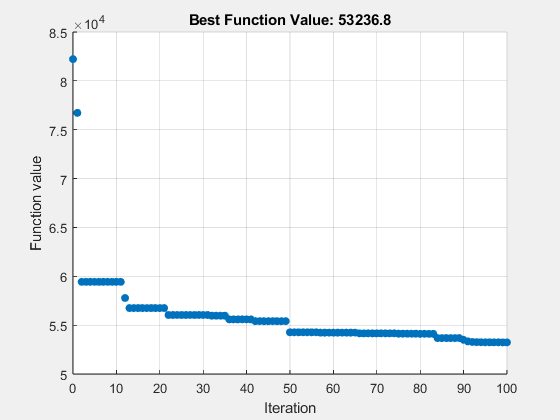

% Set nondefault solver options
options2 = optimoptions("particleswarm","InertiaRange",Inertia_range,...
    "SelfAdjustmentWeight",2.8,"SocialAdjustmentWeight",1.3,"MaxIterations",...
    100,"Display","iter","PlotFcn","pswplotbestf");

% Solve
[sol,obj] = particleswarm(@tunning,numvar,lower_bounds,...
    upper_bounds,options2);


% Clear variables
clearvars options2